# Parameterization of the Michaelis Menten Growth Model

%% Enzyme kinetics or a population approaching carrying capacity follow a saturating function

% The Michaelis-Menten equation is commonly used to describe these processes, 

% v = vm * [S] / ks + [S], 

% where v is the initial reaction velocity, vm

% is the maximum initial reaction velocity, [S] is the substrate

% concentration, and ks is the half-saturation constant.

% The following data represent a reaction that may follow the above relation.

S = [1.3 1.8 3 4.5 6 8 9];
v = [0.07 0.13 0.22 0.275 0.335 0.35 0.36];

% Plotting the data we see that indeed the trend seems to indicate a

% saturating process is represented by the data.

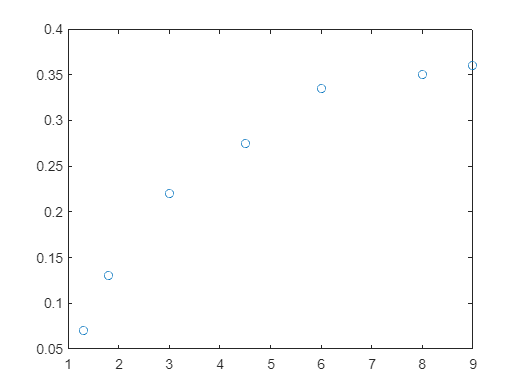

plot(S,v,'o')

%% Lineweaver-Burk method

% Inverting the relationship allows us to linearize and may allow us to use

% linear regression to fit the data. 

% 1/v = 1/vm + ks / vm(1/[S])

% Let's plot 1/v versus 1/[S] to see how it looks.

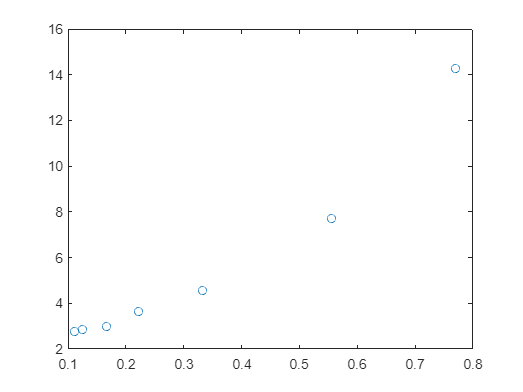

figure
plot(S.^(-1),v.^(-1),'o')

% Using polyfit, let's see how a linear best fit looks

a4 = polyfit(S.^(-1),v.^(-1),1)

a4 =    16.4022    0.1902


vfit = polyval(a4,S.^(-1));

% Inspect data and fit

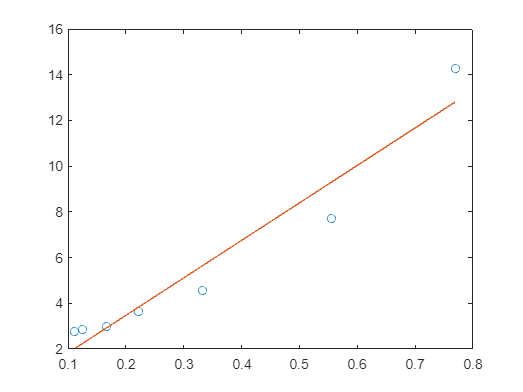

figure
plot(S.^(-1),v.^(-1),'o')
hold on
plot(S.^(-1),vfit)
hold off

% We can use the coefficients from polyfit to determine vm and ks.

vm1 = 1/a4(2)

vm1 = 5.2570

ks1 = vm1*a4(1)

ks1 = 86.2260

% Evaluate the coefficient of determination

SStot = sum((v.^(-1)-mean(v.^(-1))).^2);     % Total Sum-Of-Squares
SSres = sum((v.^(-1)-vfit).^2);              % Residual Sum-Of-Squares
R2_MM1 = 1-SSres/SStot                       % R^2

R2_MM1 = 0.9344

% With R² of 0.93, this doesn't look too bad. Let's plot the fuction on the

% original axes to see how the trend looks.

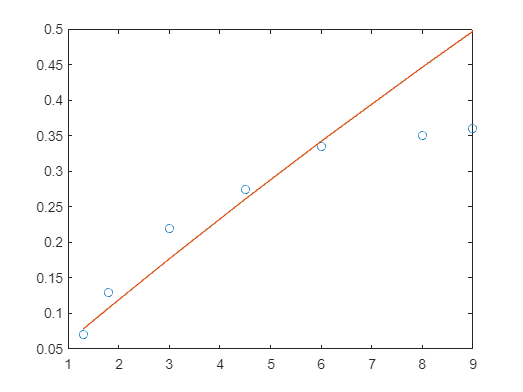

figure
plot(S,v,'o')
hold on
plot(S,(vfit.^(-1)))
hold off

%%

% Hummm... Well, the fitted function doesn't seem to saturate in the way

% the data would suggest.  

% Let's see what we can do.

% There is another form of the M-M equation, for allosteric enzymes, that

% takes the form:

% v = vm[S]^2 / ks^2 + [S]^2.

% Inverting the relationship allows us to linearize and may allow us to use

% linear regression to fit the data.

% 1/v = 1/vm + ks^2/vm (1/[S]^2)

% Let's plot 1/v versus 1/[S]^2 to see how it looks.

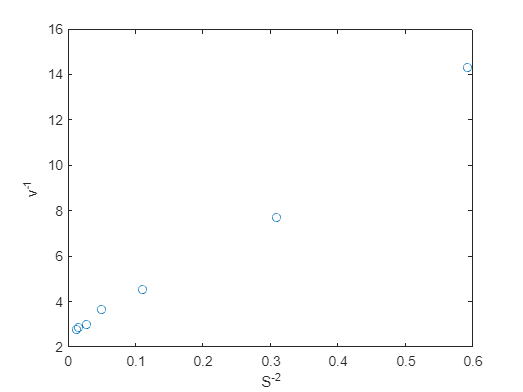

figure
plot(S.^(-2),v.^(-1),'o'); xlabel('S^{-2}'); ylabel('v^{-1}')

%%

% Using polyfit, let's see how a linear best fit looks

a5 = polyfit(S.^(-2),v.^(-1),1)

a5 =    19.3760    2.4492


vfit2 = polyval(a5,S.^(-2));

% Inspect data and fit

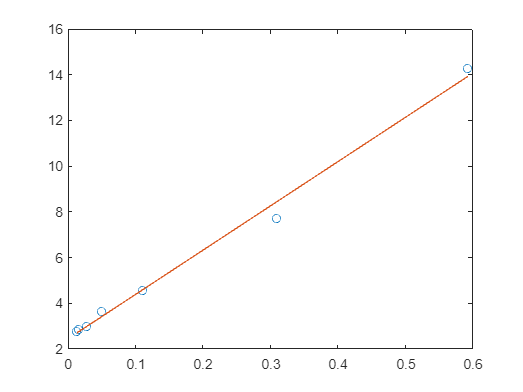

figure
plot(S.^(-2),v.^(-1),'o')
hold on
plot(S.^(-2),vfit2)
hold off

%%

% We can use the coefficients from polyfit to determine vm and ks.

vm2 = 1/a5(2)

vm2 = 0.4083

ks2 = sqrt(vm2*a5(1))

ks2 = 2.8127

% Evaluate the coefficient of determination

SStot = sum((v.^(-1)-mean(v.^(-1))).^2);     % Total Sum-Of-Squares
SSres = sum((v.^(-1)-vfit2).^2);              % Residual Sum-Of-Squares
R2_MM2 = 1-SSres/SStot                       % R^2

R2_MM2 = 0.9929

% With R² of 0.93, this doesn't look too bad. Let's plot the fuction on the

% original axes to see how the trend looks.

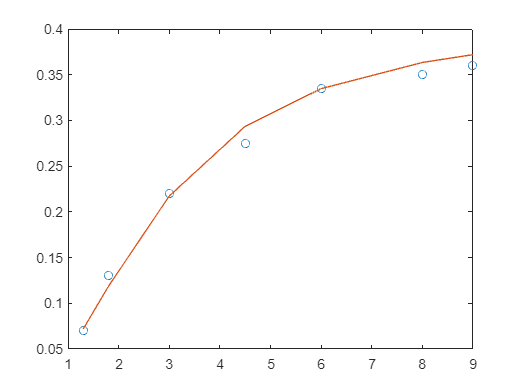

figure
plot(S,v,'o')
hold on
plot(S,(vfit2.^(-1)))
hold off